# ACM 11 Week 9 In-Class Exercise 2

## Classification of the Fisher iris data set

#### **(0) Names of all group members: **

Kyle McGraw, Dallas Taylor

This exercise requires that MATLAB's Statistics and Machine Learning Toolbox be installed. To see if you have this installed, type "`help mnrfit`" in the command line. If it comes up with documentation for the function, you are all set. If it displays a message that says the toolbox is required, you can click the link in the message to install the toolbox (It is included with the Caltech license but not a default download).

In this exercise explore using MATLAB's built-in classifiers to classify flowers in the Fisher iris data set. The data consists of 150 data points. Each datum consists of 4 measurements of the flower: sepal length, sepal width, petal length, and petal width; plus the flower species name. The code block below loads the data set and uses the `GSCATTER` command to make scatter plots of the measurement data grouped by species.

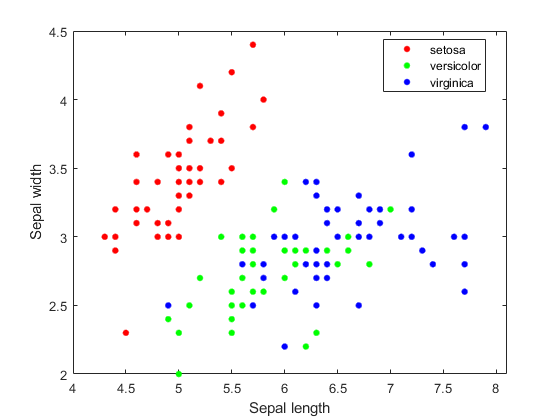

clear

load fisheriris; 

gscatter(meas(:,1),meas(:,2),species)
xlabel('Sepal length')
ylabel('Sepal width')

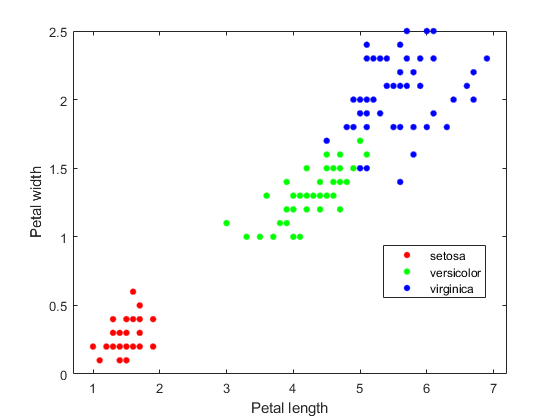


gscatter(meas(:,3),meas(:,4),species)
xlabel('Petal length')
ylabel('Petal width')

### Binary classification using `MNRFIT`

We will now use the built-in function `MNRFIT` to do a binary classification as to whether a species is *Iris virginica* or not. The `MNRFIT` function for binary variables does a logistic regression. It can actually do more categories too, but we'll stick to binary since that's what we covered for logistic regression in class.

First we make a binary variable $y$ that is 1 for Iris virgnica and 0 for the other two species.

y = strcmp(species,'virginica');

Next we divide our data into a training and a test set. Note that the data are ordered, so we need to randomly shuffle the data points in order to avoid accidentally training only on not-virginica samples. Since the results will change depending on the random permutation of the data, I'm giving you a random seed that leads to interesting results (if you fix a random seed then the randomness becomes reproducable).

load rng_seed
rng(seed)
P = randperm(150); % returns a random ordering of the integers 1:150
Xshuffle = meas(P,:); % shuffles measurement data according to P
yshuffle = y(P);

Ntrain = 100;

Xtrain = Xshuffle(1:Ntrain,:);
ytrain = yshuffle(1:Ntrain);
Xtest = Xshuffle(Ntrain+1:end,:);
ytest = yshuffle(Ntrain+1:end);

We now call MNRFIT on the training data to fit a logistic regression model. To do so, we have to use the function `CATEGORICAL` on the y-data. We can then use the function MNRVAL to evaluate the model on the training and test data. Note that MNRVAL returns two values for each evaluation point; they are the probability that the data can be assigned the value 0 and 1, respectively. We can choose the threshold $\tau$ for how large a probability should be before it gets assigned to 1.

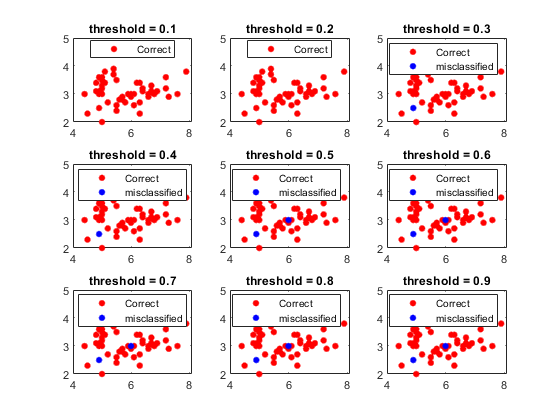

model = mnrfit(Xtrain,categorical(ytrain));

model_pred_train = mnrval(model,Xtrain);
model_pred_test = mnrval(model,Xtest);

tau_vals = 0.1:0.1:0.9;
miss_rate = zeros(length(tau_vals),2);
figure; p = 1;
for i = 1:length(tau_vals)
    y_pred_train = model_pred_train > tau_vals(i);
    y_pred_test = model_pred_test > tau_vals(i);
    
    miss_rate(i,1) = sum(y_pred_train(:,2)~=ytrain)/length(ytrain);
    miss_rate(i,2) = sum(y_pred_test(:,2)~=ytest)/length(ytest);
    
    subplot(3,3,p)
    gscatter(Xtest(:,1),Xtest(:,2),y_pred_test(:,2)~=ytest,'rb')
    legend('Correct','misclassified')
    title(['threshold = ',num2str(tau_vals(i))])
    p = p+1;
end

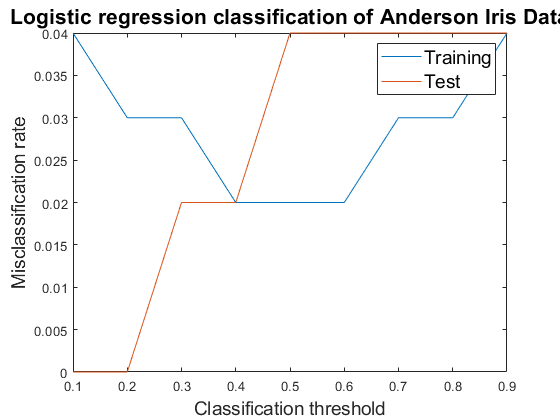


figure
plot(tau_vals,miss_rate)
xlabel('Classification threshold','FontSize',14)
ylabel('Misclassification rate','FontSize',14)
legend('Training','Test','FontSize',14)
title('Logistic regression classification of Anderson Iris Data','FontSize',16)

**(1a) Note how the prediction values are calculated using a specified threshold in lines 34-35, and note how we calculate the misclassification rate in lines 37-38. If you have any questions about why this works, ask!**

**(1b) How does the misclassification rate on the training data vary as we vary the threshold for classifying based on the logistic regression?**

**The rate goes down and then back up.**

**(1c) How does the misclassification rate on the test data vary as the threshold is varied?**

**The rate goes up as the threshold is increased.**

**(1d) Based on your results, what threshold would you choose for making future predictions outside the available data?**

**I would choose a threshold of 0.15 since 0.1-0.2 have the smallest test misclassification rate.**

### **Categorical classifcation using k-nearest neighbors**

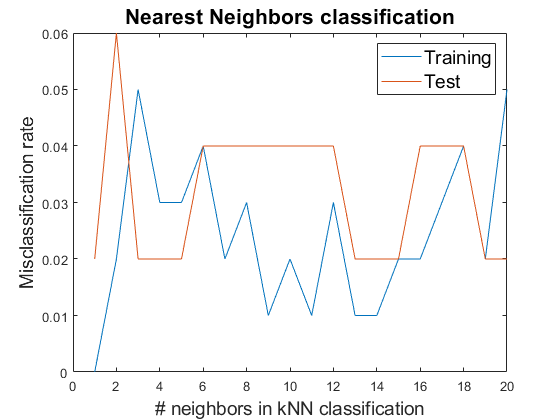

k_vals = 1:20;

miss_rate = zeros(length(k_vals),2);
for k = k_vals
    model = fitcknn(Xtrain,ytrain,'NumNeighbors',k);
    
    y_pred_train = predict(model, Xtrain);
    y_pred_test = predict(model, Xtest);
    
    miss_rate(k,1) = sum(y_pred_train~=ytrain)/length(ytrain);
    miss_rate(k,2) = sum(y_pred_test~=ytest)/length(ytest);
    
end

figure;
plot(k_vals, miss_rate)
xlabel('# neighbors in kNN classification','FontSize',14)
ylabel('Misclassification rate','FontSize',14)
legend('Training','Test','FontSize',14)
title('Nearest Neighbors classification','FontSize',16)

**(2a) How does the misclassification rate on the training data vary as we vary the # neighbors used for classification? For what value of *****k***** is the training error minimized?**

**The rate fluctuates but seems to decrease from 3 to around 9-14 neighbors and then increase with more neighbors. Training error seems to be minimized with 0 at 1 neighbor otherwise at 9, 11, 13, and 14.**

**(2b) How does the misclassification rate on the test data vary as the # neighbors is varied?**

**The rate seems to fluctuate around the same value for all neighbors.**

**(2c) Based on your results, how many neighbors would you choose for making future predictions outside the available data?**

**I would probably choose 14 neighbors since it is minimized for both test and train.**